# king_raw.mat Data Cleaning

King_Building_Test

David Olson

04 Sep 2021

% Start Fresh
close all
clear all
clc

% Define Constants
Fs = 50; % Hz - confirmed via hand-written notes
dt = 1 / Fs;
init_time = 11.5; % Time spent sitting still before test for initialization

% Load Raw Data
load("king_raw.mat")

## Accelerometer Data Cleaning

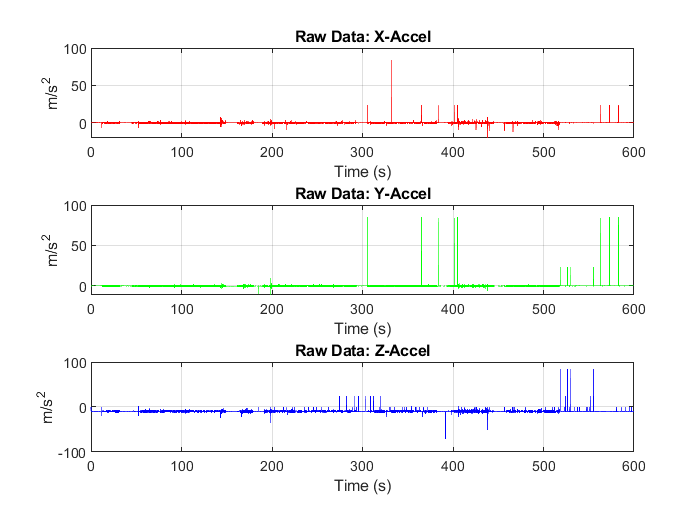

% Plot Data to see how it looks
figure(1)
subplot(3,1,1)
plot(t, accel(:,1), 'r')
title('Raw Data: X-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,2)
plot(t, accel(:,2), 'g')
title('Raw Data: Y-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,3)
plot(t, accel(:,3), 'b')
title('Raw Data: Z-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on

**Data looks good, no need for adjustment**

## Gyroscope Data Cleaning

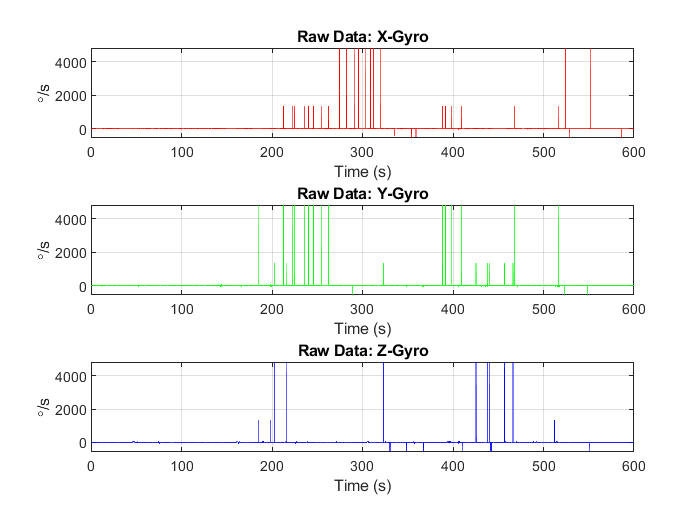

% Plot Data to see how it looks
figure(2)
subplot(3,1,1)
plot(t, gyro(:,1) * 180/pi, 'r')
title('Raw Data: X-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,2)
plot(t, gyro(:,2) * 180/pi, 'g')
title('Raw Data: Y-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,3)
plot(t, gyro(:,3) * 180/pi, 'b')
title('Raw Data: Z-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on

**Data looks good, no need for adjustment**

Y-gyro spikes hard as expected with tilt from the robot

## Odometry Data Cleaning

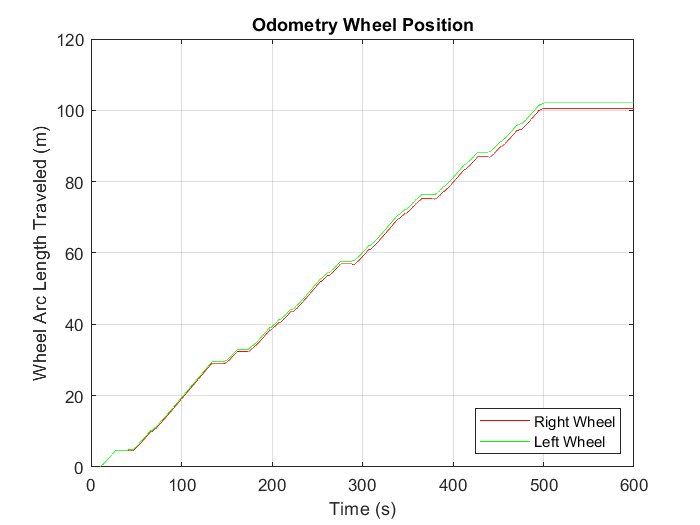

figure(3)
plot(t, odo(:,1), 'r', t, odo(:,2), 'g')
title('Odometry Wheel Position')
xlabel('Time (s)')
ylabel('Wheel Arc Length Traveled (m)')
legend('Right Wheel', 'Left Wheel', 'Location', "SouthEast")
grid on

**Data looks good, no need for adjustment**

## **Depth Camera Data Cleaning**

   
% Pre-Allocate
[kinect_samples, ~] = size(depth);
numPoints = 5000;
xyz = zeros(3, numPoints, kinect_samples);

% Convert to XYZ with down-sampling
tic
for k = 2 : kinect_samples
    xyz(:,:,k) = depth2xyz(depth, numPoints, k);
end
toc

Elapsed time is 134.070498 seconds.


## Depth Camera Animation

% % Show Animation
% for k = 2 : kinect_samples
%     
%     figure
%     hold on
%     plot3(xyz(1,:,k), xyz(2,:,k), xyz(3,:,k), 'b.');
%     viscircles([0,0], 0.35, 'Color', 'k');
%     quiver3(0,0,0,0.5,0,0, 'Color', 'r', 'LineWidth', 3);
%     title(['Kinect Point Cloud:   t = ', num2str(k)])
%     xlabel('X (m)')
%     ylabel('Y (m)')
%     zlabel('Z (m)')
%     xlim([-0.5 3.5])
%     
%     axis equal
%     view([-156.521 13.341])
%     grid on
%     hold off
%     
% %     pause(1)
%     
% %     dummy = input('Hit Enter to Move to Next Frame, Hit Q to Quit:  ', "s");
% %     if (dummy == 'Q')
% %         break
% %     end
% %     clf(4)
% %     clc
%     
% end

% Establish Point Cloud Processing Parameters
[~, K, num_frames] = size(xyz);

% Convert 3D Matrix into Cell Array
new_xyz = cell(num_frames,1);
for n = 1 : num_frames
    new_xyz{n} = xyz(:,:,n);
end
xyz = new_xyz;

## Separate Point Cloud Data into Wall and Floor Points

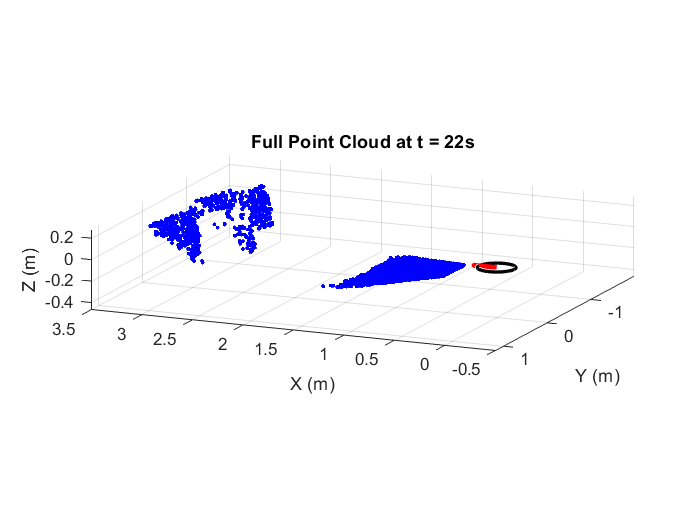

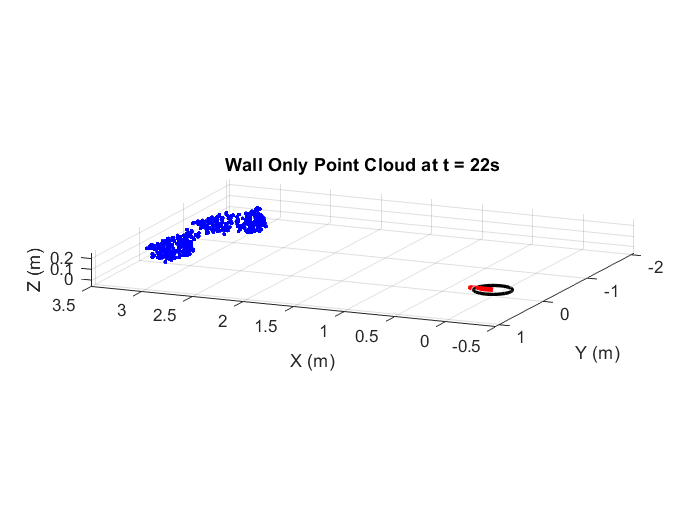

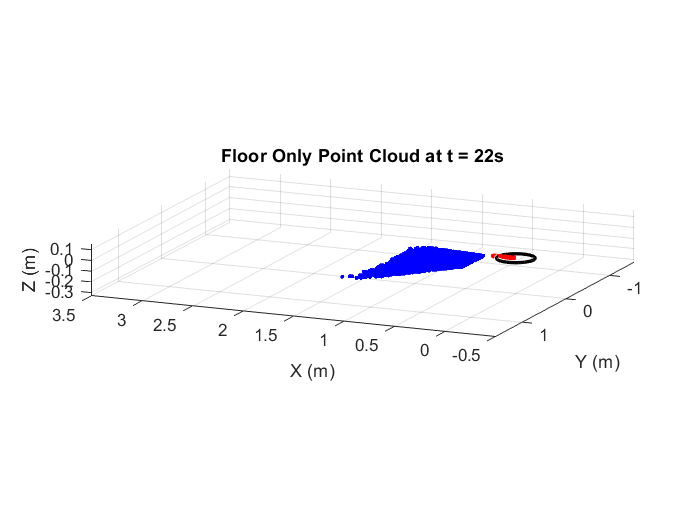

% Define Thresholds
x_thres = 1.5;
z_thres = 0;

% Separate Points
xyz_wall = cell(num_frames,1);
xyz_floor = cell(num_frames,1);

for n = 2 : num_frames
    
    % Remove all {0;0;0] measurements
    zero_mask = logical(sum(xyz{n}) ~= 0);
    xyz{n} = xyz{n}(:,zero_mask);
    
    % Locate and Store floor points
    floor_mask = (xyz{n}(1,:) < x_thres) & (xyz{n}(3,:) < z_thres);
    xyz_floor{n} = xyz{n}(:,floor_mask);
    
    % Locate and Store wall points
    wall_mask = (xyz{n}(3,:) >= z_thres);
    xyz_wall{n} = xyz{n}(:,wall_mask);
    
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Thresholding
test_point_cloud_flag = true;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz{test_frame}, ['Full Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
end

## Verify the attitude of the floor with a quick test case

% % Verify Good Floor Data
% test_frame = 22;
% plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
% % Pitch of two Example Points
% atan2(-0.03661 - -0.03142, 1.316 - 0.4602) * 180/pi
% % Accomplish Crude Prediction of "Ground Truth" Pitch Values
% pitch = zeros(1, num_frames);
% for n = 2 : num_frames
%     
%     % Grab and Average All Points between x = 0.5 & x = 0.6
%     xyz_floor_back_mask = (xyz_floor{n}(1,:) > 0.5) & (xyz_floor{n}(1,:) < 0.6);
%     xyz_back_avg = mean(xyz_floor{n}(:,xyz_floor_back_mask)')';
%     
%     % Grab and Average All Points between x = 0.9 & x = 0.1
%     xyz_floor_front_mask = (xyz_floor{n}(1,:) > 0.9) & (xyz_floor{n}(1,:) < 1);
%     xyz_front_avg = mean(xyz_floor{n}(:,xyz_floor_front_mask)')';
%     
%     pitch(n) = atan2(xyz_front_avg(3) - xyz_back_avg(3), xyz_front_avg(1) - xyz_back_avg(1));
%     
% end
% 
% % Plot "Ground Truth" Estimate of Pitch
% plot(2:num_frames, pitch(2:end) * 180/pi, 'g*')
% title('"Ground Truth" Pitch Guesses')
% xlabel('Frames')
% xlim([2 num_frames])
% ylabel('Pitch (\circ)')
% grid on

## Shift Wall and Floor Point Clouds to the Origin

% Locate and Shift each floor point cloud to the origin
% for n = 2 : num_frames
% %     x_max = max(xyz_floor{n}(1,:));
% %     x_min = min(xyz_floor{n}(1,:));
% %     x_shift = x_min + ((x_max - x_min)/2);
% %     y_max = max(xyz_floor{n}(2,:));
% %     y_min = min(xyz_floor{n}(2,:));
% %     y_shift = y_min + ((y_max - y_min)/2);
%     xyz_floor{n} = xyz_floor{n} - [0.5; 0; 0];
% end
% 
% Locate and Shift each wall point cloud to the origin
% for n = 2 : num_frames
%     x_max = max(xyz_wall{n}(1,:));
%     x_min = min(xyz_wall{n}(1,:));
%     x_shift = x_min + ((x_max - x_min)/2);
%     xyz_wall{n} = xyz_wall{n} - [x_shift; 0; 0];
% end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Point Cloud Shifting
test_point_cloud_flag = true;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    hold on
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
%     quiver3(0,0,0,cos(3*pi/180),0,sin(3*pi/180))
    hold off
end

## Complete the SNHT Floor Search

Searching for pitch only!

Begin Processing Frame #2

Elapsed time is 1.152106 seconds.


Begin Processing Frame #3

Elapsed time is 1.142817 seconds.


Begin Processing Frame #4

Elapsed time is 1.100262 seconds.


Begin Processing Frame #5

Elapsed time is 1.113712 seconds.


Begin Processing Frame #6

Elapsed time is 1.124918 seconds.


Begin Processing Frame #7

Elapsed time is 1.091337 seconds.


Begin Processing Frame #8

Elapsed time is 1.133017 seconds.


Begin Processing Frame #9

Elapsed time is 1.106475 seconds.


Begin Processing Frame #10

Elapsed time is 1.112703 seconds.


Begin Processing Frame #11

Elapsed time is 1.141900 seconds.


Begin Processing Frame #12

Elapsed time is 1.122872 seconds.


Begin Processing Frame #13

Elapsed time is 1.174449 seconds.


Begin Processing Frame #14

Elapsed time is 1.195660 seconds.


Begin Processing Frame #15

Elapsed time is 1.170847 seconds.


Begin Processing Frame #16

Elapsed time is 1.189831 seconds.


Begin Processing Frame #17

Elapsed time is 1.230784 seconds.


Begin Processing Frame #18

Elapsed time is 1.276470 seconds.


Begin Processing Frame #19

Elapsed time is 1.313199 seconds.


Begin Processing Frame #20

Elapsed time is 1.388922 seconds.


Begin Processing Frame #21

Elapsed time is 1.390720 seconds.


Begin Processing Frame #22

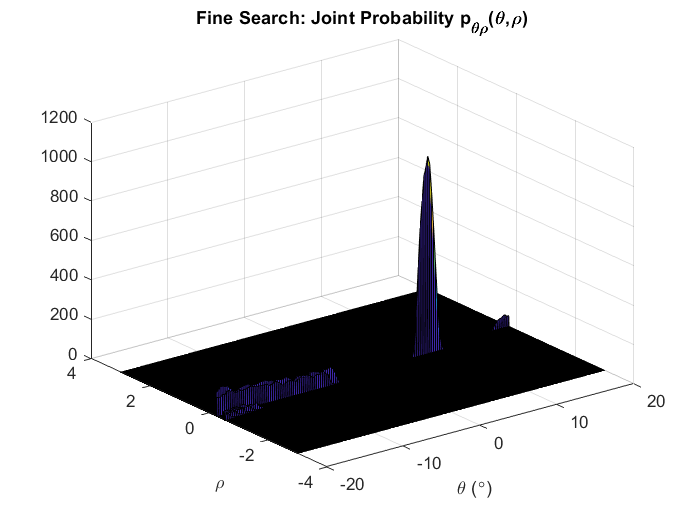

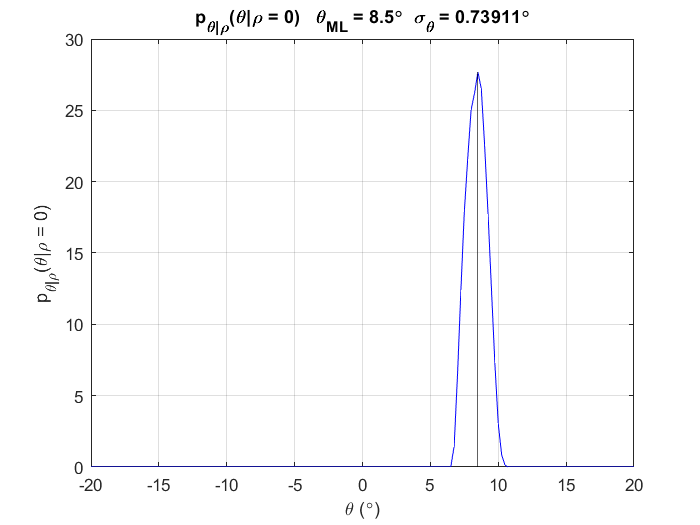

Elapsed time is 1.495615 seconds.


Begin Processing Frame #23

Elapsed time is 0.923984 seconds.


Begin Processing Frame #24

Elapsed time is 0.909864 seconds.


Begin Processing Frame #25

Elapsed time is 0.879771 seconds.


Begin Processing Frame #26

Elapsed time is 0.840529 seconds.


Begin Processing Frame #27

Elapsed time is 0.825921 seconds.


Begin Processing Frame #28

Elapsed time is 1.083238 seconds.


Begin Processing Frame #29

Elapsed time is 1.001081 seconds.


Begin Processing Frame #30

Elapsed time is 0.913380 seconds.


Begin Processing Frame #31

Elapsed time is 0.920465 seconds.


Begin Processing Frame #32

Elapsed time is 0.914316 seconds.


Begin Processing Frame #33

Elapsed time is 0.905915 seconds.


Begin Processing Frame #34

Elapsed time is 0.903434 seconds.


Begin Processing Frame #35

Elapsed time is 0.929936 seconds.


Begin Processing Frame #36

Elapsed time is 0.909677 seconds.


Begin Processing Frame #37

Elapsed time is 0.941470 seconds.


Begin Processing Frame #38

Elapsed time is 0.932063 seconds.


Begin Processing Frame #39

Elapsed time is 0.914135 seconds.


Begin Processing Frame #40

Elapsed time is 0.918688 seconds.


Begin Processing Frame #41

Elapsed time is 0.907665 seconds.


Begin Processing Frame #42

Elapsed time is 0.910511 seconds.


Begin Processing Frame #43

Elapsed time is 0.925478 seconds.


Begin Processing Frame #44

Elapsed time is 1.136119 seconds.


Begin Processing Frame #45

Elapsed time is 1.132551 seconds.


Begin Processing Frame #46

Elapsed time is 1.181166 seconds.


Begin Processing Frame #47

Elapsed time is 1.148058 seconds.


Begin Processing Frame #48

Elapsed time is 1.081792 seconds.


Begin Processing Frame #49

Elapsed time is 1.124019 seconds.


Begin Processing Frame #50

Elapsed time is 1.156948 seconds.


Begin Processing Frame #51

Elapsed time is 1.212724 seconds.


Begin Processing Frame #52

Elapsed time is 1.242919 seconds.


Begin Processing Frame #53

Elapsed time is 1.274288 seconds.


Begin Processing Frame #54

Elapsed time is 1.210915 seconds.


Begin Processing Frame #55

Elapsed time is 1.171311 seconds.


Begin Processing Frame #56

Elapsed time is 1.148942 seconds.


Begin Processing Frame #57

Elapsed time is 1.126888 seconds.


Begin Processing Frame #58

Elapsed time is 1.108125 seconds.


Begin Processing Frame #59

Elapsed time is 1.127052 seconds.


Begin Processing Frame #60

Elapsed time is 1.137554 seconds.


Begin Processing Frame #61

Elapsed time is 1.113439 seconds.


Begin Processing Frame #62

Elapsed time is 1.107167 seconds.


Begin Processing Frame #63

Elapsed time is 1.118801 seconds.


Begin Processing Frame #64

Elapsed time is 1.117676 seconds.


Begin Processing Frame #65

Elapsed time is 1.121992 seconds.


Begin Processing Frame #66

Elapsed time is 1.147604 seconds.


Begin Processing Frame #67

Elapsed time is 1.183431 seconds.


Begin Processing Frame #68

Elapsed time is 1.191779 seconds.


Begin Processing Frame #69

Elapsed time is 1.176951 seconds.


Begin Processing Frame #70

Elapsed time is 1.196305 seconds.


Begin Processing Frame #71

Elapsed time is 1.219287 seconds.


Begin Processing Frame #72

Elapsed time is 1.128147 seconds.


Begin Processing Frame #73

Elapsed time is 1.139627 seconds.


Begin Processing Frame #74

Elapsed time is 1.121911 seconds.


Begin Processing Frame #75

Elapsed time is 1.151353 seconds.


Begin Processing Frame #76

Elapsed time is 1.110719 seconds.


Begin Processing Frame #77

Elapsed time is 1.136157 seconds.


Begin Processing Frame #78

Elapsed time is 1.177708 seconds.


Begin Processing Frame #79

Elapsed time is 1.202240 seconds.


Begin Processing Frame #80

Elapsed time is 1.128464 seconds.


Begin Processing Frame #81

Elapsed time is 1.153323 seconds.


Begin Processing Frame #82

Elapsed time is 1.142962 seconds.


Begin Processing Frame #83

Elapsed time is 1.146433 seconds.


Begin Processing Frame #84

Elapsed time is 1.174600 seconds.


Begin Processing Frame #85

Elapsed time is 1.163883 seconds.


Begin Processing Frame #86

Elapsed time is 1.122403 seconds.


Begin Processing Frame #87

Elapsed time is 1.104693 seconds.


Begin Processing Frame #88

Elapsed time is 1.154177 seconds.


Begin Processing Frame #89

Elapsed time is 1.133870 seconds.


Begin Processing Frame #90

Elapsed time is 1.119718 seconds.


Begin Processing Frame #91

Elapsed time is 1.168104 seconds.


Begin Processing Frame #92

Elapsed time is 1.151441 seconds.


Begin Processing Frame #93

Elapsed time is 1.159338 seconds.


Begin Processing Frame #94

Elapsed time is 1.131424 seconds.


Begin Processing Frame #95

Elapsed time is 1.147310 seconds.


Begin Processing Frame #96

Elapsed time is 1.162804 seconds.


Begin Processing Frame #97

Elapsed time is 1.164933 seconds.


Begin Processing Frame #98

Elapsed time is 1.136626 seconds.


Begin Processing Frame #99

Elapsed time is 1.113694 seconds.


Begin Processing Frame #100

Elapsed time is 1.141714 seconds.


Begin Processing Frame #101

Elapsed time is 1.119827 seconds.


Begin Processing Frame #102

Elapsed time is 1.071522 seconds.


Begin Processing Frame #103

Elapsed time is 1.145085 seconds.


Begin Processing Frame #104

Elapsed time is 1.152681 seconds.


Begin Processing Frame #105

Elapsed time is 1.143619 seconds.


Begin Processing Frame #106

Elapsed time is 1.145065 seconds.


Begin Processing Frame #107

Elapsed time is 1.125322 seconds.


Begin Processing Frame #108

Elapsed time is 1.140749 seconds.


Begin Processing Frame #109

Elapsed time is 1.155848 seconds.


Begin Processing Frame #110

Elapsed time is 1.173680 seconds.


Begin Processing Frame #111

Elapsed time is 1.147416 seconds.


Begin Processing Frame #112

Elapsed time is 1.180226 seconds.


Begin Processing Frame #113

Elapsed time is 1.155058 seconds.


Begin Processing Frame #114

Elapsed time is 1.126527 seconds.


Begin Processing Frame #115

Elapsed time is 1.146501 seconds.


Begin Processing Frame #116

Elapsed time is 1.146456 seconds.


Begin Processing Frame #117

Elapsed time is 1.136984 seconds.


Begin Processing Frame #118

Elapsed time is 1.145721 seconds.


Begin Processing Frame #119

Elapsed time is 1.131427 seconds.


Begin Processing Frame #120

Elapsed time is 1.111656 seconds.


Begin Processing Frame #121

Elapsed time is 1.161708 seconds.


Begin Processing Frame #122

Elapsed time is 1.160661 seconds.


Begin Processing Frame #123

Elapsed time is 1.276504 seconds.


Begin Processing Frame #124

Elapsed time is 1.286126 seconds.


Begin Processing Frame #125

Elapsed time is 1.200966 seconds.


Begin Processing Frame #126

Elapsed time is 1.204138 seconds.


Begin Processing Frame #127

Elapsed time is 1.252810 seconds.


Begin Processing Frame #128

Elapsed time is 1.229839 seconds.


Begin Processing Frame #129

Elapsed time is 1.198400 seconds.


Begin Processing Frame #130

Elapsed time is 1.113384 seconds.


Begin Processing Frame #131

Elapsed time is 1.029791 seconds.


Begin Processing Frame #132

Elapsed time is 1.012681 seconds.


Begin Processing Frame #133

Elapsed time is 1.036975 seconds.


Begin Processing Frame #134

Elapsed time is 1.027895 seconds.


Begin Processing Frame #135

Elapsed time is 1.053078 seconds.


Begin Processing Frame #136

Elapsed time is 1.103415 seconds.


Begin Processing Frame #137

Elapsed time is 1.111090 seconds.


Begin Processing Frame #138

Elapsed time is 1.022622 seconds.


Begin Processing Frame #139

Elapsed time is 1.070161 seconds.


Begin Processing Frame #140

Elapsed time is 1.044307 seconds.


Begin Processing Frame #141

Elapsed time is 1.036519 seconds.


Begin Processing Frame #142

Elapsed time is 1.030589 seconds.


Begin Processing Frame #143

Elapsed time is 1.063525 seconds.


Begin Processing Frame #144

Elapsed time is 1.045330 seconds.


Begin Processing Frame #145

Elapsed time is 1.021478 seconds.


Begin Processing Frame #146

Elapsed time is 1.026034 seconds.


Begin Processing Frame #147

Elapsed time is 1.033965 seconds.


Begin Processing Frame #148

Elapsed time is 1.235728 seconds.


Begin Processing Frame #149

Elapsed time is 1.228910 seconds.


Begin Processing Frame #150

Elapsed time is 1.225027 seconds.


Begin Processing Frame #151

Elapsed time is 1.243129 seconds.


Begin Processing Frame #152

Elapsed time is 1.207674 seconds.


Begin Processing Frame #153

Elapsed time is 1.237671 seconds.


Begin Processing Frame #154

Elapsed time is 1.292883 seconds.


Begin Processing Frame #155

Elapsed time is 1.187266 seconds.


Begin Processing Frame #156

Elapsed time is 1.113051 seconds.


Begin Processing Frame #157

Elapsed time is 1.075130 seconds.


Begin Processing Frame #158

Elapsed time is 1.019567 seconds.


Begin Processing Frame #159

Elapsed time is 0.943853 seconds.


Begin Processing Frame #160

Elapsed time is 0.875710 seconds.


Begin Processing Frame #161

Elapsed time is 0.962007 seconds.


Begin Processing Frame #162

Elapsed time is 0.969664 seconds.


Begin Processing Frame #163

Elapsed time is 0.960775 seconds.


Begin Processing Frame #164

Elapsed time is 0.940271 seconds.


Begin Processing Frame #165

Elapsed time is 0.911549 seconds.


Begin Processing Frame #166

Elapsed time is 0.920219 seconds.


Begin Processing Frame #167

Elapsed time is 0.925408 seconds.


Begin Processing Frame #168

Elapsed time is 0.912916 seconds.


Begin Processing Frame #169

Elapsed time is 0.906881 seconds.


Begin Processing Frame #170

Elapsed time is 0.902074 seconds.


Begin Processing Frame #171

Elapsed time is 0.905457 seconds.


Begin Processing Frame #172

Elapsed time is 0.928683 seconds.


Begin Processing Frame #173

Elapsed time is 0.925131 seconds.


Begin Processing Frame #174

Elapsed time is 0.928864 seconds.


Begin Processing Frame #175

Elapsed time is 1.162147 seconds.


Begin Processing Frame #176

Elapsed time is 1.145074 seconds.


Begin Processing Frame #177

Elapsed time is 1.179298 seconds.


Begin Processing Frame #178

Elapsed time is 1.164941 seconds.


Begin Processing Frame #179

Elapsed time is 1.127967 seconds.


Begin Processing Frame #180

Elapsed time is 1.169653 seconds.


Begin Processing Frame #181

Elapsed time is 1.124180 seconds.


Begin Processing Frame #182

Elapsed time is 1.141907 seconds.


Begin Processing Frame #183

Elapsed time is 1.141507 seconds.


Begin Processing Frame #184

Elapsed time is 1.175817 seconds.


Begin Processing Frame #185

Elapsed time is 1.167808 seconds.


Begin Processing Frame #186

Elapsed time is 1.173489 seconds.


Begin Processing Frame #187

Elapsed time is 1.117555 seconds.


Begin Processing Frame #188

Elapsed time is 1.111685 seconds.


Begin Processing Frame #189

Elapsed time is 1.162681 seconds.


Begin Processing Frame #190

Elapsed time is 1.110547 seconds.


Begin Processing Frame #191

Elapsed time is 1.082691 seconds.


Begin Processing Frame #192

Elapsed time is 1.135103 seconds.


Begin Processing Frame #193

Elapsed time is 1.159374 seconds.


Begin Processing Frame #194

Elapsed time is 1.128343 seconds.


Begin Processing Frame #195

Elapsed time is 1.161824 seconds.


Begin Processing Frame #196

Elapsed time is 1.123530 seconds.


Begin Processing Frame #197

Elapsed time is 1.151835 seconds.


Begin Processing Frame #198

Elapsed time is 1.137652 seconds.


Begin Processing Frame #199

Elapsed time is 1.143454 seconds.


Begin Processing Frame #200

Elapsed time is 1.140863 seconds.


Begin Processing Frame #201

Elapsed time is 1.076507 seconds.


Begin Processing Frame #202

Elapsed time is 1.109709 seconds.


Begin Processing Frame #203

Elapsed time is 1.153049 seconds.


Begin Processing Frame #204

Elapsed time is 1.154572 seconds.


Begin Processing Frame #205

Elapsed time is 1.160186 seconds.


Begin Processing Frame #206

Elapsed time is 1.156629 seconds.


Begin Processing Frame #207

Elapsed time is 1.172168 seconds.


Begin Processing Frame #208

Elapsed time is 1.127249 seconds.


Begin Processing Frame #209

Elapsed time is 1.148563 seconds.


Begin Processing Frame #210

Elapsed time is 1.136291 seconds.


Begin Processing Frame #211

Elapsed time is 1.148620 seconds.


Begin Processing Frame #212

Elapsed time is 1.130425 seconds.


Begin Processing Frame #213

Elapsed time is 1.143589 seconds.


Begin Processing Frame #214

Elapsed time is 1.154453 seconds.


Begin Processing Frame #215

Elapsed time is 1.116521 seconds.


Begin Processing Frame #216

Elapsed time is 1.112568 seconds.


Begin Processing Frame #217

Elapsed time is 1.144774 seconds.


Begin Processing Frame #218

Elapsed time is 1.138584 seconds.


Begin Processing Frame #219

Elapsed time is 1.165746 seconds.


Begin Processing Frame #220

Elapsed time is 1.150261 seconds.


Begin Processing Frame #221

Elapsed time is 1.145156 seconds.


Begin Processing Frame #222

Elapsed time is 1.175007 seconds.


Begin Processing Frame #223

Elapsed time is 1.139490 seconds.


Begin Processing Frame #224

Elapsed time is 1.112826 seconds.


Begin Processing Frame #225

Elapsed time is 1.125414 seconds.


Begin Processing Frame #226

Elapsed time is 1.100812 seconds.


Begin Processing Frame #227

Elapsed time is 1.132477 seconds.


Begin Processing Frame #228

Elapsed time is 1.128701 seconds.


Begin Processing Frame #229

Elapsed time is 1.121821 seconds.


Begin Processing Frame #230

Elapsed time is 1.132022 seconds.


Begin Processing Frame #231

Elapsed time is 1.153312 seconds.


Begin Processing Frame #232

Elapsed time is 1.188435 seconds.


Begin Processing Frame #233

Elapsed time is 1.196583 seconds.


Begin Processing Frame #234

Elapsed time is 1.158853 seconds.


Begin Processing Frame #235

Elapsed time is 1.156379 seconds.


Begin Processing Frame #236

Elapsed time is 1.114269 seconds.


Begin Processing Frame #237

Elapsed time is 1.131898 seconds.


Begin Processing Frame #238

Elapsed time is 1.106535 seconds.


Begin Processing Frame #239

Elapsed time is 1.121259 seconds.


Begin Processing Frame #240

Elapsed time is 1.142368 seconds.


Begin Processing Frame #241

Elapsed time is 1.111106 seconds.


Begin Processing Frame #242

Elapsed time is 1.145311 seconds.


Begin Processing Frame #243

Elapsed time is 1.135919 seconds.


Begin Processing Frame #244

Elapsed time is 1.115300 seconds.


Begin Processing Frame #245

Elapsed time is 1.181863 seconds.


Begin Processing Frame #246

Elapsed time is 1.206142 seconds.


Begin Processing Frame #247

Elapsed time is 1.241342 seconds.


Begin Processing Frame #248

Elapsed time is 1.214681 seconds.


Begin Processing Frame #249

Elapsed time is 1.174594 seconds.


Begin Processing Frame #250

Elapsed time is 1.147558 seconds.


Begin Processing Frame #251

Elapsed time is 1.154971 seconds.


Begin Processing Frame #252

Elapsed time is 1.165627 seconds.


Begin Processing Frame #253

Elapsed time is 1.122303 seconds.


Begin Processing Frame #254

Elapsed time is 1.080084 seconds.


Begin Processing Frame #255

Elapsed time is 1.138949 seconds.


Begin Processing Frame #256

Elapsed time is 1.063085 seconds.


Begin Processing Frame #257

Elapsed time is 1.109121 seconds.


Begin Processing Frame #258

Elapsed time is 1.076621 seconds.


Begin Processing Frame #259

Elapsed time is 1.101187 seconds.


Begin Processing Frame #260

Elapsed time is 1.072625 seconds.


Begin Processing Frame #261

Elapsed time is 1.107343 seconds.


Begin Processing Frame #262

Elapsed time is 1.139817 seconds.


Begin Processing Frame #263

Elapsed time is 1.164455 seconds.


Begin Processing Frame #264

Elapsed time is 1.187638 seconds.


Begin Processing Frame #265

Elapsed time is 1.170894 seconds.


Begin Processing Frame #266

Elapsed time is 1.199108 seconds.


Begin Processing Frame #267

Elapsed time is 1.263837 seconds.


Begin Processing Frame #268

Elapsed time is 1.288631 seconds.


Begin Processing Frame #269

Elapsed time is 1.212181 seconds.


Begin Processing Frame #270

Elapsed time is 1.136134 seconds.


Begin Processing Frame #271

Elapsed time is 1.142655 seconds.


Begin Processing Frame #272

Elapsed time is 1.147590 seconds.


Begin Processing Frame #273

Elapsed time is 1.103753 seconds.


Begin Processing Frame #274

Elapsed time is 1.114174 seconds.


Begin Processing Frame #275

Elapsed time is 1.145295 seconds.


Begin Processing Frame #276

Elapsed time is 1.146490 seconds.


Begin Processing Frame #277

Elapsed time is 1.142742 seconds.


Begin Processing Frame #278

Elapsed time is 1.129474 seconds.


Begin Processing Frame #279

Elapsed time is 1.111068 seconds.


Begin Processing Frame #280

Elapsed time is 1.109551 seconds.


Begin Processing Frame #281

Elapsed time is 1.107810 seconds.


Begin Processing Frame #282

Elapsed time is 1.080361 seconds.


Begin Processing Frame #283

Elapsed time is 1.093239 seconds.


Begin Processing Frame #284

Elapsed time is 1.144849 seconds.


Begin Processing Frame #285

Elapsed time is 1.125270 seconds.


Begin Processing Frame #286

Elapsed time is 1.121961 seconds.


Begin Processing Frame #287

Elapsed time is 1.129389 seconds.


Begin Processing Frame #288

Elapsed time is 1.109739 seconds.


Begin Processing Frame #289

Elapsed time is 1.111429 seconds.


Begin Processing Frame #290

Elapsed time is 1.171235 seconds.


Begin Processing Frame #291

Elapsed time is 1.042820 seconds.


Begin Processing Frame #292

Elapsed time is 1.118613 seconds.


Begin Processing Frame #293

Elapsed time is 1.115519 seconds.


Begin Processing Frame #294

Elapsed time is 1.155598 seconds.


Begin Processing Frame #295

Elapsed time is 1.145695 seconds.


Begin Processing Frame #296

Elapsed time is 1.190378 seconds.


Begin Processing Frame #297

Elapsed time is 1.165957 seconds.


Begin Processing Frame #298

Elapsed time is 1.180430 seconds.


Begin Processing Frame #299

Elapsed time is 1.143261 seconds.


Begin Processing Frame #300

Elapsed time is 1.113520 seconds.


Begin Processing Frame #301

Elapsed time is 1.138783 seconds.


Begin Processing Frame #302

Elapsed time is 1.154790 seconds.


Begin Processing Frame #303

Elapsed time is 1.157688 seconds.


Begin Processing Frame #304

Elapsed time is 1.153264 seconds.


Begin Processing Frame #305

Elapsed time is 1.174614 seconds.


Begin Processing Frame #306

Elapsed time is 1.192403 seconds.


Begin Processing Frame #307

Elapsed time is 1.191854 seconds.


Begin Processing Frame #308

Elapsed time is 1.150631 seconds.


Begin Processing Frame #309

Elapsed time is 1.164649 seconds.


Begin Processing Frame #310

Elapsed time is 1.141319 seconds.


Begin Processing Frame #311

Elapsed time is 1.164085 seconds.


Begin Processing Frame #312

Elapsed time is 1.194610 seconds.


Begin Processing Frame #313

Elapsed time is 1.174163 seconds.


Begin Processing Frame #314

Elapsed time is 1.132867 seconds.


Begin Processing Frame #315

Elapsed time is 1.155639 seconds.


Begin Processing Frame #316

Elapsed time is 1.118715 seconds.


Begin Processing Frame #317

Elapsed time is 1.133144 seconds.


Begin Processing Frame #318

Elapsed time is 1.137938 seconds.


Begin Processing Frame #319

Elapsed time is 1.185898 seconds.


Begin Processing Frame #320

Elapsed time is 1.187529 seconds.


Begin Processing Frame #321

Elapsed time is 1.160226 seconds.


Begin Processing Frame #322

Elapsed time is 1.158079 seconds.


Begin Processing Frame #323

Elapsed time is 1.154062 seconds.


Begin Processing Frame #324

Elapsed time is 1.122138 seconds.


Begin Processing Frame #325

Elapsed time is 1.113827 seconds.


Begin Processing Frame #326

Elapsed time is 1.074695 seconds.


Begin Processing Frame #327

Elapsed time is 1.112787 seconds.


Begin Processing Frame #328

Elapsed time is 1.128308 seconds.


Begin Processing Frame #329

Elapsed time is 1.126721 seconds.


Begin Processing Frame #330

Elapsed time is 1.094814 seconds.


Begin Processing Frame #331

Elapsed time is 1.119512 seconds.


Begin Processing Frame #332

Elapsed time is 1.181457 seconds.


Begin Processing Frame #333

Elapsed time is 1.213278 seconds.


Begin Processing Frame #334

Elapsed time is 1.192216 seconds.


Begin Processing Frame #335

Elapsed time is 1.183017 seconds.


Begin Processing Frame #336

Elapsed time is 1.150816 seconds.


Begin Processing Frame #337

Elapsed time is 1.160267 seconds.


Begin Processing Frame #338

Elapsed time is 1.136617 seconds.


Begin Processing Frame #339

Elapsed time is 1.150653 seconds.


Begin Processing Frame #340

Elapsed time is 1.127862 seconds.


Begin Processing Frame #341

Elapsed time is 1.144418 seconds.


Begin Processing Frame #342

Elapsed time is 1.135440 seconds.


Begin Processing Frame #343

Elapsed time is 1.122423 seconds.


Begin Processing Frame #344

Elapsed time is 1.112887 seconds.


Begin Processing Frame #345

Elapsed time is 1.164106 seconds.


Begin Processing Frame #346

Elapsed time is 1.139489 seconds.


Begin Processing Frame #347

Elapsed time is 1.172101 seconds.


Begin Processing Frame #348

Elapsed time is 1.217272 seconds.


Begin Processing Frame #349

Elapsed time is 1.331075 seconds.


Begin Processing Frame #350

Elapsed time is 1.226203 seconds.


Begin Processing Frame #351

Elapsed time is 1.257000 seconds.


Begin Processing Frame #352

Elapsed time is 1.291093 seconds.


Begin Processing Frame #353

Elapsed time is 1.305557 seconds.


Begin Processing Frame #354

Elapsed time is 1.283268 seconds.


Begin Processing Frame #355

Elapsed time is 1.299451 seconds.


Begin Processing Frame #356

Elapsed time is 1.316805 seconds.


Begin Processing Frame #357

Elapsed time is 1.360446 seconds.


Begin Processing Frame #358

Elapsed time is 1.356295 seconds.


Begin Processing Frame #359

Elapsed time is 1.357608 seconds.


Begin Processing Frame #360

Elapsed time is 1.431607 seconds.


Begin Processing Frame #361

Elapsed time is 1.485740 seconds.


Begin Processing Frame #362

Elapsed time is 1.365996 seconds.


Begin Processing Frame #363

Elapsed time is 1.286306 seconds.


Begin Processing Frame #364

Elapsed time is 0.997112 seconds.


Begin Processing Frame #365

Elapsed time is 0.948002 seconds.


Begin Processing Frame #366

Elapsed time is 0.861249 seconds.


Begin Processing Frame #367

Elapsed time is 0.823658 seconds.


Begin Processing Frame #368

Elapsed time is 0.733731 seconds.


Begin Processing Frame #369

Elapsed time is 0.757019 seconds.


Begin Processing Frame #370

Elapsed time is 0.737442 seconds.


Begin Processing Frame #371

Elapsed time is 0.745076 seconds.


Begin Processing Frame #372

Elapsed time is 0.740107 seconds.


Begin Processing Frame #373

Elapsed time is 0.745066 seconds.


Begin Processing Frame #374

Elapsed time is 0.714970 seconds.


Begin Processing Frame #375

Elapsed time is 0.733875 seconds.


Begin Processing Frame #376

Elapsed time is 0.731601 seconds.


Begin Processing Frame #377

Elapsed time is 0.759686 seconds.


Begin Processing Frame #378

Elapsed time is 0.723719 seconds.


Begin Processing Frame #379

Elapsed time is 0.845210 seconds.


Begin Processing Frame #380

Elapsed time is 1.138163 seconds.


Begin Processing Frame #381

Elapsed time is 1.182748 seconds.


Begin Processing Frame #382

Elapsed time is 1.167816 seconds.


Begin Processing Frame #383

Elapsed time is 1.150587 seconds.


Begin Processing Frame #384

Elapsed time is 1.152077 seconds.


Begin Processing Frame #385

Elapsed time is 1.225611 seconds.


Begin Processing Frame #386

Elapsed time is 1.284353 seconds.


Begin Processing Frame #387

Elapsed time is 1.291658 seconds.


Begin Processing Frame #388

Elapsed time is 1.314094 seconds.


Begin Processing Frame #389

Elapsed time is 1.289424 seconds.


Begin Processing Frame #390

Elapsed time is 1.309217 seconds.


Begin Processing Frame #391

Elapsed time is 1.233170 seconds.


Begin Processing Frame #392

Elapsed time is 1.253030 seconds.


Begin Processing Frame #393

Elapsed time is 1.275895 seconds.


Begin Processing Frame #394

Elapsed time is 1.322389 seconds.


Begin Processing Frame #395

Elapsed time is 1.308911 seconds.


Begin Processing Frame #396

Elapsed time is 1.298075 seconds.


Begin Processing Frame #397

Elapsed time is 1.246084 seconds.


Begin Processing Frame #398

Elapsed time is 1.225207 seconds.


Begin Processing Frame #399

Elapsed time is 1.205128 seconds.


Begin Processing Frame #400

Elapsed time is 1.219978 seconds.


Begin Processing Frame #401

Elapsed time is 1.251793 seconds.


Begin Processing Frame #402

Elapsed time is 1.281907 seconds.


Begin Processing Frame #403

Elapsed time is 1.256733 seconds.


Begin Processing Frame #404

Elapsed time is 1.269368 seconds.


Begin Processing Frame #405

Elapsed time is 1.236274 seconds.


Begin Processing Frame #406

Elapsed time is 1.225764 seconds.


Begin Processing Frame #407

Elapsed time is 1.235541 seconds.


Begin Processing Frame #408

Elapsed time is 1.248956 seconds.


Begin Processing Frame #409

Elapsed time is 1.207836 seconds.


Begin Processing Frame #410

Elapsed time is 1.238962 seconds.


Begin Processing Frame #411

Elapsed time is 1.268751 seconds.


Begin Processing Frame #412

Elapsed time is 1.357206 seconds.


Begin Processing Frame #413

Elapsed time is 1.396059 seconds.


Begin Processing Frame #414

Elapsed time is 1.356616 seconds.


Begin Processing Frame #415

Elapsed time is 1.359788 seconds.


Begin Processing Frame #416

Elapsed time is 1.392991 seconds.


Begin Processing Frame #417

Elapsed time is 1.458371 seconds.


Begin Processing Frame #418

Elapsed time is 1.427356 seconds.


Begin Processing Frame #419

Elapsed time is 1.318806 seconds.


Begin Processing Frame #420

Elapsed time is 1.258919 seconds.


Begin Processing Frame #421

Elapsed time is 1.198584 seconds.


Begin Processing Frame #422

Elapsed time is 1.117499 seconds.


Begin Processing Frame #423

Elapsed time is 1.156465 seconds.


Begin Processing Frame #424

Elapsed time is 1.045353 seconds.


Begin Processing Frame #425

Elapsed time is 0.987672 seconds.


Begin Processing Frame #426

Elapsed time is 0.955146 seconds.


Begin Processing Frame #427

Elapsed time is 1.011991 seconds.


Begin Processing Frame #428

Elapsed time is 1.012381 seconds.


Begin Processing Frame #429

Elapsed time is 0.975945 seconds.


Begin Processing Frame #430

Elapsed time is 0.928865 seconds.


Begin Processing Frame #431

Elapsed time is 0.925709 seconds.


Begin Processing Frame #432

Elapsed time is 0.913127 seconds.


Begin Processing Frame #433

Elapsed time is 0.922844 seconds.


Begin Processing Frame #434

Elapsed time is 0.925548 seconds.


Begin Processing Frame #435

Elapsed time is 0.925018 seconds.


Begin Processing Frame #436

Elapsed time is 0.892312 seconds.


Begin Processing Frame #437

Elapsed time is 0.891505 seconds.


Begin Processing Frame #438

Elapsed time is 0.905229 seconds.


Begin Processing Frame #439

Elapsed time is 0.895618 seconds.


Begin Processing Frame #440

Elapsed time is 0.893300 seconds.


Begin Processing Frame #441

Elapsed time is 0.912589 seconds.


Begin Processing Frame #442

Elapsed time is 1.145592 seconds.


Begin Processing Frame #443

Elapsed time is 1.096838 seconds.


Begin Processing Frame #444

Elapsed time is 1.155343 seconds.


Begin Processing Frame #445

Elapsed time is 1.168664 seconds.


Begin Processing Frame #446

Elapsed time is 1.157281 seconds.


Begin Processing Frame #447

Elapsed time is 1.195340 seconds.


Begin Processing Frame #448

Elapsed time is 1.199926 seconds.


Begin Processing Frame #449

Elapsed time is 1.179901 seconds.


Begin Processing Frame #450

Elapsed time is 1.172778 seconds.


Begin Processing Frame #451

Elapsed time is 1.140926 seconds.


Begin Processing Frame #452

Elapsed time is 1.096493 seconds.


Begin Processing Frame #453

Elapsed time is 1.107975 seconds.


Begin Processing Frame #454

Elapsed time is 1.110552 seconds.


Begin Processing Frame #455

Elapsed time is 1.132209 seconds.


Begin Processing Frame #456

Elapsed time is 1.144826 seconds.


Begin Processing Frame #457

Elapsed time is 1.155667 seconds.


Begin Processing Frame #458

Elapsed time is 1.151074 seconds.


Begin Processing Frame #459

Elapsed time is 1.123183 seconds.


Begin Processing Frame #460

Elapsed time is 1.160923 seconds.


Begin Processing Frame #461

Elapsed time is 1.127569 seconds.


Begin Processing Frame #462

Elapsed time is 1.140326 seconds.


Begin Processing Frame #463

Elapsed time is 1.175896 seconds.


Begin Processing Frame #464

Elapsed time is 1.168056 seconds.


Begin Processing Frame #465

Elapsed time is 1.153667 seconds.


Begin Processing Frame #466

Elapsed time is 1.114306 seconds.


Begin Processing Frame #467

Elapsed time is 1.108594 seconds.


Begin Processing Frame #468

Elapsed time is 1.134425 seconds.


Begin Processing Frame #469

Elapsed time is 1.176353 seconds.


Begin Processing Frame #470

Elapsed time is 1.179688 seconds.


Begin Processing Frame #471

Elapsed time is 1.144254 seconds.


Begin Processing Frame #472

Elapsed time is 1.136955 seconds.


Begin Processing Frame #473

Elapsed time is 1.157223 seconds.


Begin Processing Frame #474

Elapsed time is 1.119584 seconds.


Begin Processing Frame #475

Elapsed time is 1.125923 seconds.


Begin Processing Frame #476

Elapsed time is 1.088909 seconds.


Begin Processing Frame #477

Elapsed time is 1.122365 seconds.


Begin Processing Frame #478

Elapsed time is 1.096156 seconds.


Begin Processing Frame #479

Elapsed time is 1.129919 seconds.


Begin Processing Frame #480

Elapsed time is 1.116481 seconds.


Begin Processing Frame #481

Elapsed time is 1.080402 seconds.


Begin Processing Frame #482

Elapsed time is 1.134048 seconds.


Begin Processing Frame #483

Elapsed time is 1.147607 seconds.


Begin Processing Frame #484

Elapsed time is 1.168337 seconds.


Begin Processing Frame #485

Elapsed time is 1.148721 seconds.


Begin Processing Frame #486

Elapsed time is 1.163406 seconds.


Begin Processing Frame #487

Elapsed time is 1.177628 seconds.


Begin Processing Frame #488

Elapsed time is 1.155126 seconds.


Begin Processing Frame #489

Elapsed time is 1.130456 seconds.


Begin Processing Frame #490

Elapsed time is 1.129583 seconds.


Begin Processing Frame #491

Elapsed time is 1.121209 seconds.


Begin Processing Frame #492

Elapsed time is 1.146703 seconds.


Begin Processing Frame #493

Elapsed time is 1.132974 seconds.


Begin Processing Frame #494

Elapsed time is 1.218630 seconds.


Begin Processing Frame #495

Elapsed time is 1.161836 seconds.


Begin Processing Frame #496

Elapsed time is 1.177661 seconds.


Begin Processing Frame #497

Elapsed time is 1.196499 seconds.


Begin Processing Frame #498

Elapsed time is 1.135977 seconds.


Begin Processing Frame #499

Elapsed time is 1.161858 seconds.


Begin Processing Frame #500

Elapsed time is 1.129061 seconds.


Begin Processing Frame #501

Elapsed time is 1.142814 seconds.


Begin Processing Frame #502

Elapsed time is 1.122690 seconds.


Begin Processing Frame #503

Elapsed time is 1.118906 seconds.


Begin Processing Frame #504

Elapsed time is 1.082269 seconds.


Begin Processing Frame #505

Elapsed time is 1.107875 seconds.


Begin Processing Frame #506

Elapsed time is 1.067968 seconds.


Begin Processing Frame #507

Elapsed time is 1.107739 seconds.


Begin Processing Frame #508

Elapsed time is 1.092682 seconds.


Begin Processing Frame #509

Elapsed time is 1.111427 seconds.


Begin Processing Frame #510

Elapsed time is 1.093044 seconds.


Begin Processing Frame #511

Elapsed time is 1.080885 seconds.


Begin Processing Frame #512

Elapsed time is 1.098253 seconds.


Begin Processing Frame #513

Elapsed time is 1.119482 seconds.


Begin Processing Frame #514

Elapsed time is 1.087419 seconds.


Begin Processing Frame #515

Elapsed time is 1.098090 seconds.


Begin Processing Frame #516

Elapsed time is 1.075431 seconds.


Begin Processing Frame #517

Elapsed time is 1.116831 seconds.


Begin Processing Frame #518

Elapsed time is 1.090312 seconds.


Begin Processing Frame #519

Elapsed time is 1.132488 seconds.


Begin Processing Frame #520

Elapsed time is 1.084506 seconds.


Begin Processing Frame #521

Elapsed time is 1.086359 seconds.


Begin Processing Frame #522

Elapsed time is 1.129111 seconds.


Begin Processing Frame #523

Elapsed time is 1.078721 seconds.


Begin Processing Frame #524

Elapsed time is 1.097171 seconds.


Begin Processing Frame #525

Elapsed time is 1.121627 seconds.


Begin Processing Frame #526

Elapsed time is 1.101598 seconds.


Begin Processing Frame #527

Elapsed time is 1.122742 seconds.


Begin Processing Frame #528

Elapsed time is 1.120918 seconds.


Begin Processing Frame #529

Elapsed time is 1.100637 seconds.


Begin Processing Frame #530

Elapsed time is 1.082408 seconds.


Begin Processing Frame #531

Elapsed time is 1.076411 seconds.


Begin Processing Frame #532

Elapsed time is 1.070282 seconds.


Begin Processing Frame #533

Elapsed time is 1.084084 seconds.


Begin Processing Frame #534

Elapsed time is 1.085945 seconds.


Begin Processing Frame #535

Elapsed time is 1.086488 seconds.


Begin Processing Frame #536

Elapsed time is 1.084930 seconds.


Begin Processing Frame #537

Elapsed time is 1.083036 seconds.


Begin Processing Frame #538

Elapsed time is 1.107779 seconds.


Begin Processing Frame #539

Elapsed time is 1.088812 seconds.


Begin Processing Frame #540

Elapsed time is 1.112659 seconds.


Begin Processing Frame #541

Elapsed time is 1.080175 seconds.


Begin Processing Frame #542

Elapsed time is 1.077106 seconds.


Begin Processing Frame #543

Elapsed time is 1.060161 seconds.


Begin Processing Frame #544

Elapsed time is 1.089333 seconds.


Begin Processing Frame #545

Elapsed time is 1.081443 seconds.


Begin Processing Frame #546

Elapsed time is 1.088069 seconds.


Begin Processing Frame #547

Elapsed time is 1.100027 seconds.


Begin Processing Frame #548

Elapsed time is 1.093286 seconds.


Begin Processing Frame #549

Elapsed time is 1.084740 seconds.


Begin Processing Frame #550

Elapsed time is 1.090170 seconds.


Begin Processing Frame #551

Elapsed time is 1.129444 seconds.


Begin Processing Frame #552

Elapsed time is 1.084940 seconds.


Begin Processing Frame #553

Elapsed time is 1.102066 seconds.


Begin Processing Frame #554

Elapsed time is 1.084842 seconds.


Begin Processing Frame #555

Elapsed time is 1.096017 seconds.


Begin Processing Frame #556

Elapsed time is 1.112688 seconds.


Begin Processing Frame #557

Elapsed time is 1.121269 seconds.


Begin Processing Frame #558

Elapsed time is 1.097114 seconds.


Begin Processing Frame #559

Elapsed time is 1.097188 seconds.


Begin Processing Frame #560

Elapsed time is 1.087130 seconds.


Begin Processing Frame #561

Elapsed time is 1.077416 seconds.


Begin Processing Frame #562

Elapsed time is 1.095949 seconds.


Begin Processing Frame #563

Elapsed time is 1.116794 seconds.


Begin Processing Frame #564

Elapsed time is 1.080858 seconds.


Begin Processing Frame #565

Elapsed time is 1.113212 seconds.


Begin Processing Frame #566

Elapsed time is 1.089183 seconds.


Begin Processing Frame #567

Elapsed time is 1.097184 seconds.


Begin Processing Frame #568

Elapsed time is 1.070302 seconds.


Begin Processing Frame #569

Elapsed time is 1.079453 seconds.


Begin Processing Frame #570

Elapsed time is 1.103293 seconds.


Begin Processing Frame #571

Elapsed time is 1.079371 seconds.


Begin Processing Frame #572

Elapsed time is 1.080516 seconds.


Begin Processing Frame #573

Elapsed time is 1.095562 seconds.


Begin Processing Frame #574

Elapsed time is 1.098206 seconds.


Begin Processing Frame #575

Elapsed time is 1.099521 seconds.


Begin Processing Frame #576

Elapsed time is 1.093797 seconds.


Begin Processing Frame #577

Elapsed time is 1.089010 seconds.


Begin Processing Frame #578

Elapsed time is 1.092915 seconds.


Begin Processing Frame #579

Elapsed time is 1.085389 seconds.


Begin Processing Frame #580

Elapsed time is 1.073287 seconds.


Begin Processing Frame #581

Elapsed time is 1.087784 seconds.


Begin Processing Frame #582

Elapsed time is 1.062045 seconds.


Begin Processing Frame #583

Elapsed time is 1.088496 seconds.


Begin Processing Frame #584

Elapsed time is 1.075703 seconds.


Begin Processing Frame #585

Elapsed time is 1.102918 seconds.


Begin Processing Frame #586

Elapsed time is 1.079397 seconds.


Begin Processing Frame #587

Elapsed time is 1.078063 seconds.


Begin Processing Frame #588

Elapsed time is 1.104244 seconds.


Begin Processing Frame #589

Elapsed time is 1.066383 seconds.


Begin Processing Frame #590

Elapsed time is 1.081562 seconds.


Begin Processing Frame #591

Elapsed time is 1.086468 seconds.


Begin Processing Frame #592

Elapsed time is 1.091975 seconds.


Begin Processing Frame #593

Elapsed time is 1.089660 seconds.


Begin Processing Frame #594

Elapsed time is 1.093699 seconds.


Begin Processing Frame #595

Elapsed time is 1.129969 seconds.


Begin Processing Frame #596

Elapsed time is 1.095041 seconds.


Begin Processing Frame #597

Elapsed time is 1.087071 seconds.


Begin Processing Frame #598

Elapsed time is 1.091696 seconds.


Begin Processing Frame #599

Elapsed time is 1.074400 seconds.


Begin Processing Frame #600

Elapsed time is 1.089836 seconds.


Begin Processing Frame #601

Elapsed time is 1.098168 seconds.


% Pre-Allocate Memory
theta_meas = zeros(1,91);
theta_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [theta_meas(n), theta_sigmas(n)] = SNHT_pitch(xyz_floor{n}, plot_flag);
    toc
    
end

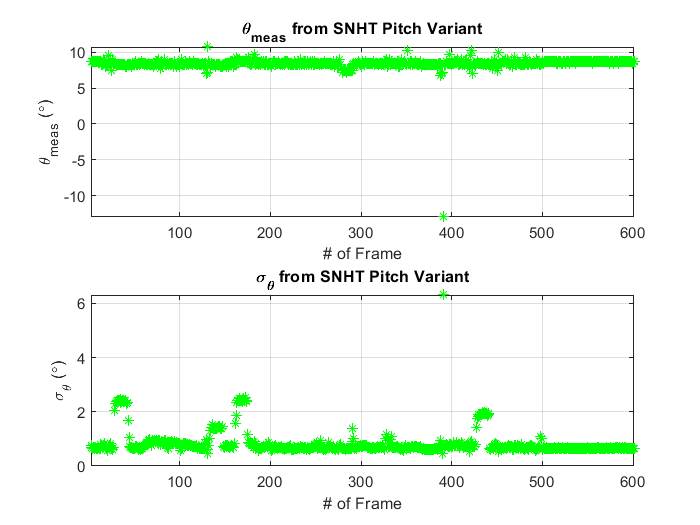

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, theta_meas * 180/pi, 'g*')
title('\theta_m_e_a_s from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\theta_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, theta_sigmas * 180/pi, 'g*')
title('\sigma_\theta from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\theta (\circ)')
grid on

## Process Wall Point Clouds

Begin Processing Frame #2

Elapsed time is 1.289307 seconds.


Begin Processing Frame #3

Elapsed time is 1.371594 seconds.


Begin Processing Frame #4

Elapsed time is 1.511362 seconds.


Begin Processing Frame #5

Elapsed time is 1.344156 seconds.


Begin Processing Frame #6

Elapsed time is 1.422615 seconds.


Begin Processing Frame #7

Elapsed time is 1.428107 seconds.


Begin Processing Frame #8

Elapsed time is 1.242357 seconds.


Begin Processing Frame #9

Elapsed time is 1.401080 seconds.


Begin Processing Frame #10

Elapsed time is 1.259990 seconds.


Begin Processing Frame #11

Elapsed time is 1.248599 seconds.


Begin Processing Frame #12

Elapsed time is 1.358159 seconds.


Begin Processing Frame #13

Elapsed time is 1.073883 seconds.


Begin Processing Frame #14

Elapsed time is 1.049430 seconds.


Begin Processing Frame #15

Elapsed time is 1.153548 seconds.


Begin Processing Frame #16

Elapsed time is 0.942843 seconds.


Begin Processing Frame #17

Elapsed time is 0.882851 seconds.


Begin Processing Frame #18

Elapsed time is 0.803856 seconds.


Begin Processing Frame #19

Elapsed time is 0.596176 seconds.


Begin Processing Frame #20

Elapsed time is 0.347147 seconds.


Begin Processing Frame #21

Elapsed time is 0.301403 seconds.


Begin Processing Frame #22

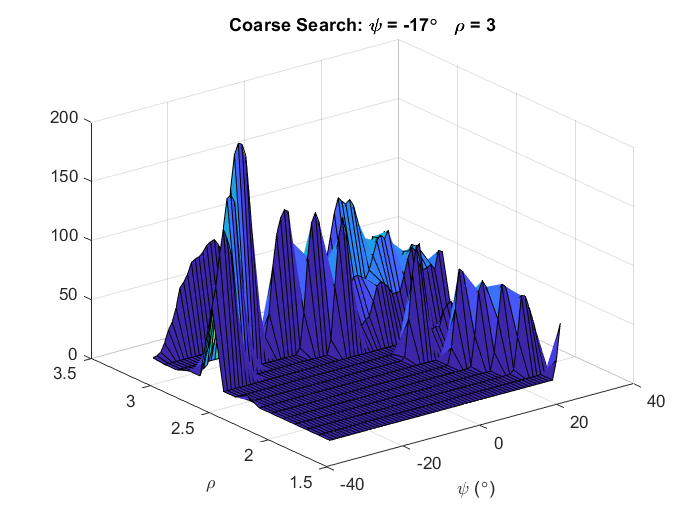

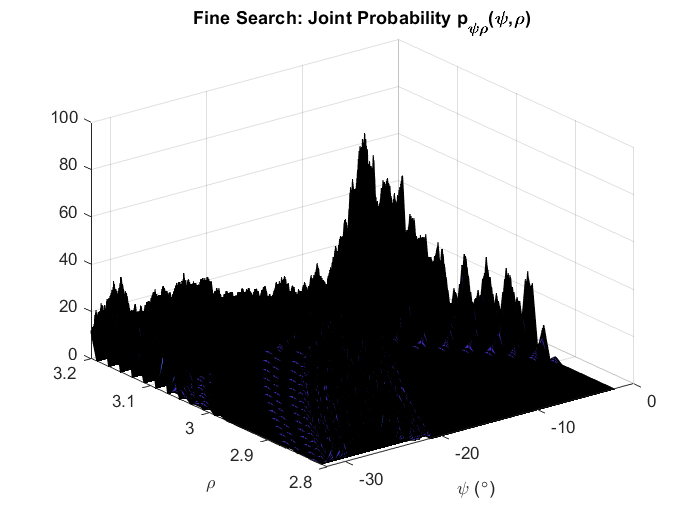

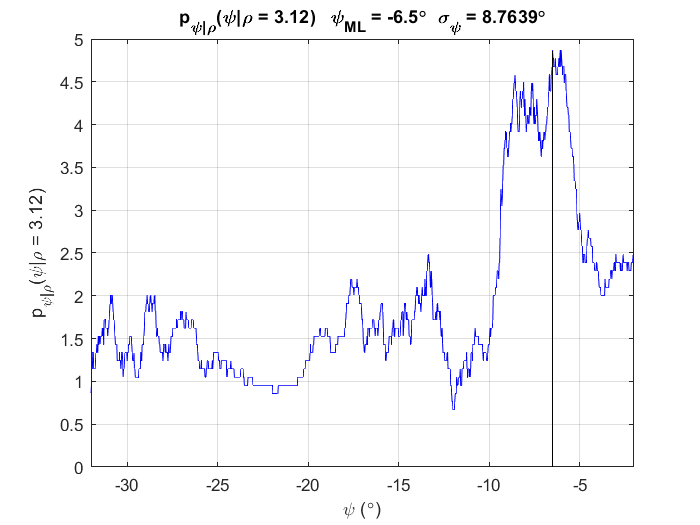

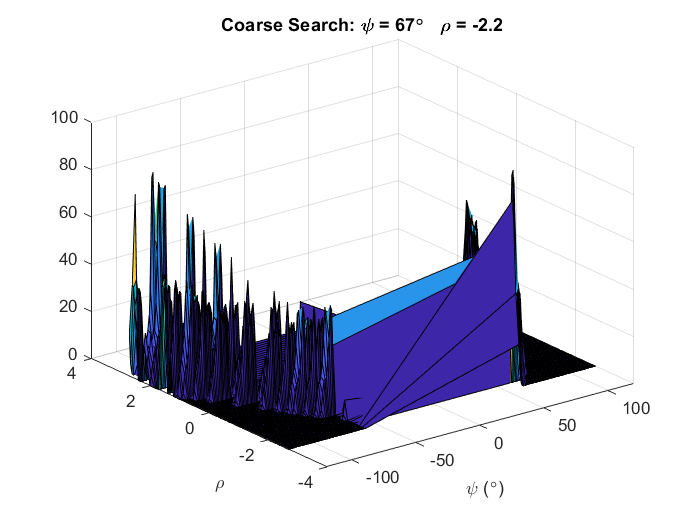

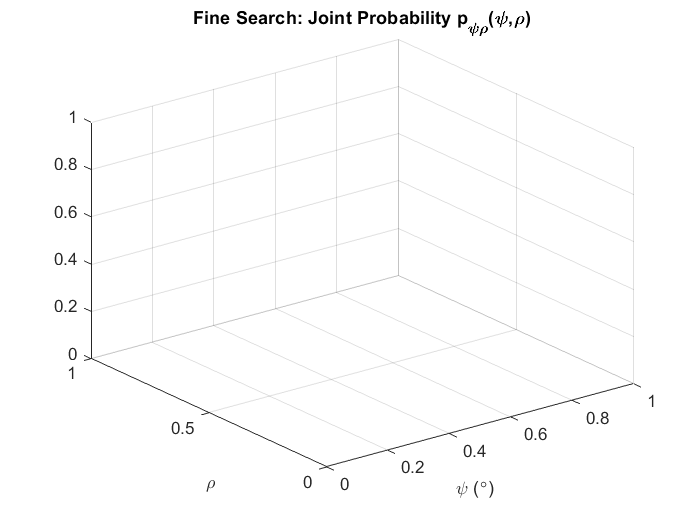

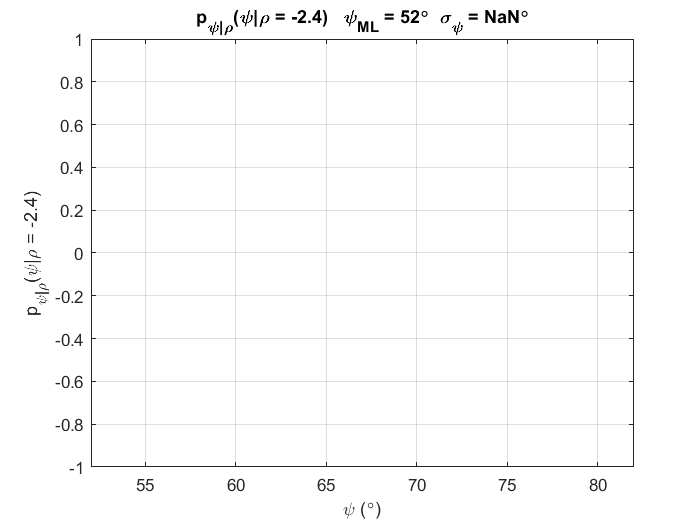

Elapsed time is 1.282530 seconds.


Begin Processing Frame #23

Elapsed time is 1.450133 seconds.


Begin Processing Frame #24

Elapsed time is 1.510604 seconds.


Begin Processing Frame #25

Elapsed time is 2.103095 seconds.


Begin Processing Frame #26

Elapsed time is 1.788895 seconds.


Begin Processing Frame #27

Elapsed time is 1.994023 seconds.


Begin Processing Frame #28

Elapsed time is 2.418435 seconds.


Begin Processing Frame #29

Elapsed time is 2.568387 seconds.


Begin Processing Frame #30

Elapsed time is 2.956687 seconds.


Begin Processing Frame #31

Elapsed time is 3.142060 seconds.


Begin Processing Frame #32

Elapsed time is 3.034543 seconds.


Begin Processing Frame #33

Elapsed time is 3.083994 seconds.


Begin Processing Frame #34

Elapsed time is 3.016792 seconds.


Begin Processing Frame #35

Elapsed time is 2.847620 seconds.


Begin Processing Frame #36

Elapsed time is 2.964902 seconds.


Begin Processing Frame #37

Elapsed time is 2.943473 seconds.


Begin Processing Frame #38

Elapsed time is 2.909353 seconds.


Begin Processing Frame #39

Elapsed time is 3.089171 seconds.


Begin Processing Frame #40

Elapsed time is 2.960993 seconds.


Begin Processing Frame #41

Elapsed time is 2.958993 seconds.


Begin Processing Frame #42

Elapsed time is 2.873637 seconds.


Begin Processing Frame #43

Elapsed time is 2.376386 seconds.


Begin Processing Frame #44

Elapsed time is 1.449695 seconds.


Begin Processing Frame #45

Elapsed time is 1.121329 seconds.


Begin Processing Frame #46

Elapsed time is 1.106621 seconds.


Begin Processing Frame #47

Elapsed time is 1.111280 seconds.


Begin Processing Frame #48

Elapsed time is 1.275291 seconds.


Begin Processing Frame #49

Elapsed time is 1.110583 seconds.


Begin Processing Frame #50

Elapsed time is 1.050620 seconds.


Begin Processing Frame #51

Elapsed time is 0.914682 seconds.


Begin Processing Frame #52

Elapsed time is 0.779493 seconds.


Begin Processing Frame #53

Elapsed time is 0.724309 seconds.


Begin Processing Frame #54

Elapsed time is 0.904996 seconds.


Begin Processing Frame #55

Elapsed time is 1.177205 seconds.


Begin Processing Frame #56

Elapsed time is 1.189053 seconds.


Begin Processing Frame #57

Elapsed time is 1.291551 seconds.


Begin Processing Frame #58

Elapsed time is 1.267541 seconds.


Begin Processing Frame #59

Elapsed time is 1.241234 seconds.


Begin Processing Frame #60

Elapsed time is 1.201463 seconds.


Begin Processing Frame #61

Elapsed time is 1.256798 seconds.


Begin Processing Frame #62

Elapsed time is 1.233066 seconds.


Begin Processing Frame #63

Elapsed time is 1.252677 seconds.


Begin Processing Frame #64

Elapsed time is 1.266226 seconds.


Begin Processing Frame #65

Elapsed time is 1.309209 seconds.


Begin Processing Frame #66

Elapsed time is 1.325401 seconds.


Begin Processing Frame #67

Elapsed time is 1.303978 seconds.


Begin Processing Frame #68

Elapsed time is 1.235878 seconds.


Begin Processing Frame #69

Elapsed time is 1.163501 seconds.


Begin Processing Frame #70

Elapsed time is 1.158409 seconds.


Begin Processing Frame #71

Elapsed time is 1.195173 seconds.


Begin Processing Frame #72

Elapsed time is 1.613732 seconds.


Begin Processing Frame #73

Elapsed time is 1.446530 seconds.


Begin Processing Frame #74

Elapsed time is 1.422719 seconds.


Begin Processing Frame #75

Elapsed time is 1.257772 seconds.


Begin Processing Frame #76

Elapsed time is 1.519135 seconds.


Begin Processing Frame #77

Elapsed time is 1.406431 seconds.


Begin Processing Frame #78

Elapsed time is 1.369908 seconds.


Begin Processing Frame #79

Elapsed time is 1.327916 seconds.


Begin Processing Frame #80

Elapsed time is 1.344878 seconds.


Begin Processing Frame #81

Elapsed time is 1.333603 seconds.


Begin Processing Frame #82

Elapsed time is 1.276203 seconds.


Begin Processing Frame #83

Elapsed time is 1.281126 seconds.


Begin Processing Frame #84

Elapsed time is 1.231146 seconds.


Begin Processing Frame #85

Elapsed time is 1.166227 seconds.


Begin Processing Frame #86

Elapsed time is 1.173626 seconds.


Begin Processing Frame #87

Elapsed time is 1.277184 seconds.


Begin Processing Frame #88

Elapsed time is 1.263073 seconds.


Begin Processing Frame #89

Elapsed time is 1.449234 seconds.


Begin Processing Frame #90

Elapsed time is 1.448885 seconds.


Begin Processing Frame #91

Elapsed time is 1.325782 seconds.


Begin Processing Frame #92

Elapsed time is 1.411316 seconds.


Begin Processing Frame #93

Elapsed time is 1.346785 seconds.


Begin Processing Frame #94

Elapsed time is 1.347572 seconds.


Begin Processing Frame #95

Elapsed time is 1.376231 seconds.


Begin Processing Frame #96

Elapsed time is 1.176440 seconds.


Begin Processing Frame #97

Elapsed time is 1.332467 seconds.


Begin Processing Frame #98

Elapsed time is 1.286885 seconds.


Begin Processing Frame #99

Elapsed time is 1.355758 seconds.


Begin Processing Frame #100

Elapsed time is 1.269874 seconds.


Begin Processing Frame #101

Elapsed time is 1.212379 seconds.


Begin Processing Frame #102

Elapsed time is 1.147164 seconds.


Begin Processing Frame #103

Elapsed time is 1.245116 seconds.


Begin Processing Frame #104

Elapsed time is 1.278125 seconds.


Begin Processing Frame #105

Elapsed time is 1.256133 seconds.


Begin Processing Frame #106

Elapsed time is 1.358256 seconds.


Begin Processing Frame #107

Elapsed time is 1.378946 seconds.


Begin Processing Frame #108

Elapsed time is 1.320243 seconds.


Begin Processing Frame #109

Elapsed time is 1.356648 seconds.


Begin Processing Frame #110

Elapsed time is 1.337581 seconds.


Begin Processing Frame #111

Elapsed time is 1.332710 seconds.


Begin Processing Frame #112

Elapsed time is 1.267971 seconds.


Begin Processing Frame #113

Elapsed time is 1.434051 seconds.


Begin Processing Frame #114

Elapsed time is 1.226389 seconds.


Begin Processing Frame #115

Elapsed time is 1.161353 seconds.


Begin Processing Frame #116

Elapsed time is 1.209107 seconds.


Begin Processing Frame #117

Elapsed time is 1.277231 seconds.


Begin Processing Frame #118

Elapsed time is 1.284906 seconds.


Begin Processing Frame #119

Elapsed time is 1.209290 seconds.


Begin Processing Frame #120

Elapsed time is 1.284780 seconds.


Begin Processing Frame #121

Elapsed time is 1.185892 seconds.


Begin Processing Frame #122

Elapsed time is 1.219362 seconds.


Begin Processing Frame #123

Elapsed time is 1.042495 seconds.


Begin Processing Frame #124

Elapsed time is 0.857989 seconds.


Begin Processing Frame #125

Elapsed time is 0.764366 seconds.


Begin Processing Frame #126

Elapsed time is 0.661984 seconds.


Begin Processing Frame #127

Elapsed time is 0.676772 seconds.


Begin Processing Frame #128

Elapsed time is 0.888804 seconds.


Begin Processing Frame #129

Elapsed time is 0.860578 seconds.


Begin Processing Frame #130

Elapsed time is 1.054734 seconds.


Begin Processing Frame #131

Elapsed time is 0.822265 seconds.


Begin Processing Frame #132

Elapsed time is 1.119492 seconds.


Begin Processing Frame #133

Elapsed time is 1.251591 seconds.


Begin Processing Frame #134

Elapsed time is 1.549427 seconds.


Begin Processing Frame #135

Elapsed time is 1.833354 seconds.


Begin Processing Frame #136

Elapsed time is 2.105652 seconds.


Begin Processing Frame #137

Elapsed time is 1.956828 seconds.


Begin Processing Frame #138

Elapsed time is 1.965503 seconds.


Begin Processing Frame #139

Elapsed time is 1.808908 seconds.


Begin Processing Frame #140

Elapsed time is 1.922991 seconds.


Begin Processing Frame #141

Elapsed time is 1.939034 seconds.


Begin Processing Frame #142

Elapsed time is 1.961532 seconds.


Begin Processing Frame #143

Elapsed time is 1.816776 seconds.


Begin Processing Frame #144

Elapsed time is 1.844521 seconds.


Begin Processing Frame #145

Elapsed time is 1.907470 seconds.


Begin Processing Frame #146

Elapsed time is 1.918856 seconds.


Begin Processing Frame #147

Elapsed time is 1.992127 seconds.


Begin Processing Frame #148

Elapsed time is 0.486448 seconds.


Begin Processing Frame #149

Elapsed time is 0.561431 seconds.


Begin Processing Frame #150

Elapsed time is 0.577433 seconds.


Begin Processing Frame #151

Elapsed time is 0.541345 seconds.


Begin Processing Frame #152

Elapsed time is 0.495352 seconds.


Begin Processing Frame #153

Elapsed time is 0.481872 seconds.


Begin Processing Frame #154

Elapsed time is 0.578235 seconds.


Begin Processing Frame #155

Elapsed time is 0.765534 seconds.


Begin Processing Frame #156

Elapsed time is 0.947512 seconds.


Begin Processing Frame #157

Elapsed time is 1.218193 seconds.


Begin Processing Frame #158

Elapsed time is 1.587964 seconds.


Begin Processing Frame #159

Elapsed time is 1.733947 seconds.


Begin Processing Frame #160

Elapsed time is 1.922987 seconds.


Begin Processing Frame #161

Elapsed time is 1.919497 seconds.


Begin Processing Frame #162

Elapsed time is 2.527873 seconds.


Begin Processing Frame #163

Elapsed time is 2.824639 seconds.


Begin Processing Frame #164

Elapsed time is 2.906447 seconds.


Begin Processing Frame #165

Elapsed time is 3.282809 seconds.


Begin Processing Frame #166

Elapsed time is 3.115099 seconds.


Begin Processing Frame #167

Elapsed time is 3.177005 seconds.


Begin Processing Frame #168

Elapsed time is 3.227844 seconds.


Begin Processing Frame #169

Elapsed time is 3.185599 seconds.


Begin Processing Frame #170

Elapsed time is 3.277733 seconds.


Begin Processing Frame #171

Elapsed time is 3.329610 seconds.


Begin Processing Frame #172

Elapsed time is 3.206961 seconds.


Begin Processing Frame #173

Elapsed time is 3.113627 seconds.


Begin Processing Frame #174

Elapsed time is 3.135188 seconds.


Begin Processing Frame #175

Elapsed time is 1.422877 seconds.


Begin Processing Frame #176

Elapsed time is 0.998350 seconds.


Begin Processing Frame #177

Elapsed time is 1.030532 seconds.


Begin Processing Frame #178

Elapsed time is 1.199694 seconds.


Begin Processing Frame #179

Elapsed time is 1.303434 seconds.


Begin Processing Frame #180

Elapsed time is 1.133730 seconds.


Begin Processing Frame #181

Elapsed time is 1.368825 seconds.


Begin Processing Frame #182

Elapsed time is 1.151822 seconds.


Begin Processing Frame #183

Elapsed time is 1.222938 seconds.


Begin Processing Frame #184

Elapsed time is 1.128368 seconds.


Begin Processing Frame #185

Elapsed time is 1.134035 seconds.


Begin Processing Frame #186

Elapsed time is 1.100796 seconds.


Begin Processing Frame #187

Elapsed time is 1.291006 seconds.


Begin Processing Frame #188

Elapsed time is 1.305302 seconds.


Begin Processing Frame #189

Elapsed time is 1.140465 seconds.


Begin Processing Frame #190

Elapsed time is 1.196173 seconds.


Begin Processing Frame #191

Elapsed time is 1.195193 seconds.


Begin Processing Frame #192

Elapsed time is 1.318874 seconds.


Begin Processing Frame #193

Elapsed time is 1.260752 seconds.


Begin Processing Frame #194

Elapsed time is 1.274787 seconds.


Begin Processing Frame #195

Elapsed time is 1.182861 seconds.


Begin Processing Frame #196

Elapsed time is 1.357055 seconds.


Begin Processing Frame #197

Elapsed time is 1.353222 seconds.


Begin Processing Frame #198

Elapsed time is 1.372687 seconds.


Begin Processing Frame #199

Elapsed time is 1.351733 seconds.


Begin Processing Frame #200

Elapsed time is 1.145729 seconds.


Begin Processing Frame #201

Elapsed time is 1.488859 seconds.


Begin Processing Frame #202

Elapsed time is 1.328304 seconds.


Begin Processing Frame #203

Elapsed time is 1.082218 seconds.


Begin Processing Frame #204

Elapsed time is 1.153989 seconds.


Begin Processing Frame #205

Elapsed time is 1.235242 seconds.


Begin Processing Frame #206

Elapsed time is 1.263209 seconds.


Begin Processing Frame #207

Elapsed time is 1.129643 seconds.


Begin Processing Frame #208

Elapsed time is 1.255867 seconds.


Begin Processing Frame #209

Elapsed time is 1.220226 seconds.


Begin Processing Frame #210

Elapsed time is 1.233899 seconds.


Begin Processing Frame #211

Elapsed time is 1.253151 seconds.


Begin Processing Frame #212

Elapsed time is 1.313069 seconds.


Begin Processing Frame #213

Elapsed time is 1.331604 seconds.


Begin Processing Frame #214

Elapsed time is 1.266613 seconds.


Begin Processing Frame #215

Elapsed time is 1.271444 seconds.


Begin Processing Frame #216

Elapsed time is 1.420940 seconds.


Begin Processing Frame #217

Elapsed time is 1.238824 seconds.


Begin Processing Frame #218

Elapsed time is 1.233443 seconds.


Begin Processing Frame #219

Elapsed time is 1.106310 seconds.


Begin Processing Frame #220

Elapsed time is 1.169211 seconds.


Begin Processing Frame #221

Elapsed time is 1.195787 seconds.


Begin Processing Frame #222

Elapsed time is 1.167795 seconds.


Begin Processing Frame #223

Elapsed time is 1.353615 seconds.


Begin Processing Frame #224

Elapsed time is 1.395526 seconds.


Begin Processing Frame #225

Elapsed time is 1.316821 seconds.


Begin Processing Frame #226

Elapsed time is 1.391350 seconds.


Begin Processing Frame #227

Elapsed time is 1.256549 seconds.


Begin Processing Frame #228

Elapsed time is 1.250772 seconds.


Begin Processing Frame #229

Elapsed time is 1.307044 seconds.


Begin Processing Frame #230

Elapsed time is 1.295749 seconds.


Begin Processing Frame #231

Elapsed time is 1.142677 seconds.


Begin Processing Frame #232

Elapsed time is 1.029559 seconds.


Begin Processing Frame #233

Elapsed time is 0.934004 seconds.


Begin Processing Frame #234

Elapsed time is 1.179511 seconds.


Begin Processing Frame #235

Elapsed time is 1.066197 seconds.


Begin Processing Frame #236

Elapsed time is 1.251199 seconds.


Begin Processing Frame #237

Elapsed time is 1.212019 seconds.


Begin Processing Frame #238

Elapsed time is 1.406895 seconds.


Begin Processing Frame #239

Elapsed time is 1.208421 seconds.


Begin Processing Frame #240

Elapsed time is 1.303371 seconds.


Begin Processing Frame #241

Elapsed time is 1.302541 seconds.


Begin Processing Frame #242

Elapsed time is 1.230950 seconds.


Begin Processing Frame #243

Elapsed time is 1.200834 seconds.


Begin Processing Frame #244

Elapsed time is 1.201447 seconds.


Begin Processing Frame #245

Elapsed time is 1.082319 seconds.


Begin Processing Frame #246

Elapsed time is 0.916591 seconds.


Begin Processing Frame #247

Elapsed time is 0.883302 seconds.


Begin Processing Frame #248

Elapsed time is 1.077352 seconds.


Begin Processing Frame #249

Elapsed time is 1.244957 seconds.


Begin Processing Frame #250

Elapsed time is 1.329934 seconds.


Begin Processing Frame #251

Elapsed time is 1.300979 seconds.


Begin Processing Frame #252

Elapsed time is 1.192069 seconds.


Begin Processing Frame #253

Elapsed time is 1.246183 seconds.


Begin Processing Frame #254

Elapsed time is 1.224932 seconds.


Begin Processing Frame #255

Elapsed time is 1.313912 seconds.


Begin Processing Frame #256

Elapsed time is 1.392957 seconds.


Begin Processing Frame #257

Elapsed time is 1.188285 seconds.


Begin Processing Frame #258

Elapsed time is 1.248942 seconds.


Begin Processing Frame #259

Elapsed time is 1.229229 seconds.


Begin Processing Frame #260

Elapsed time is 1.248715 seconds.


Begin Processing Frame #261

Elapsed time is 1.231488 seconds.


Begin Processing Frame #262

Elapsed time is 1.051740 seconds.


Begin Processing Frame #263

Elapsed time is 0.961899 seconds.


Begin Processing Frame #264

Elapsed time is 1.094398 seconds.


Begin Processing Frame #265

Elapsed time is 1.112359 seconds.


Begin Processing Frame #266

Elapsed time is 0.981779 seconds.


Begin Processing Frame #267

Elapsed time is 0.725620 seconds.


Begin Processing Frame #268

Elapsed time is 0.566511 seconds.


Begin Processing Frame #269

Elapsed time is 0.998493 seconds.


Begin Processing Frame #270

Elapsed time is 1.133745 seconds.


Begin Processing Frame #271

Elapsed time is 1.019404 seconds.


Begin Processing Frame #272

Elapsed time is 1.092581 seconds.


Begin Processing Frame #273

Elapsed time is 1.241167 seconds.


Begin Processing Frame #274

Elapsed time is 1.200631 seconds.


Begin Processing Frame #275

Elapsed time is 1.111616 seconds.


Begin Processing Frame #276

Elapsed time is 1.096889 seconds.


Begin Processing Frame #277

Elapsed time is 1.251028 seconds.


Begin Processing Frame #278

Elapsed time is 1.319094 seconds.


Begin Processing Frame #279

Elapsed time is 1.380756 seconds.


Begin Processing Frame #280

Elapsed time is 1.321475 seconds.


Begin Processing Frame #281

Elapsed time is 1.368029 seconds.


Begin Processing Frame #282

Elapsed time is 1.435508 seconds.


Begin Processing Frame #283

Elapsed time is 1.429081 seconds.


Begin Processing Frame #284

Elapsed time is 1.371289 seconds.


Begin Processing Frame #285

Elapsed time is 1.423350 seconds.


Begin Processing Frame #286

Elapsed time is 1.370073 seconds.


Begin Processing Frame #287

Elapsed time is 1.311154 seconds.


Begin Processing Frame #288

Elapsed time is 1.308774 seconds.


Begin Processing Frame #289

Elapsed time is 1.375435 seconds.


Begin Processing Frame #290

Elapsed time is 1.348614 seconds.


Begin Processing Frame #291

Elapsed time is 2.110973 seconds.


Begin Processing Frame #292

Elapsed time is 1.359746 seconds.


Begin Processing Frame #293

Elapsed time is 1.318207 seconds.


Begin Processing Frame #294

Elapsed time is 1.175587 seconds.


Begin Processing Frame #295

Elapsed time is 1.165295 seconds.


Begin Processing Frame #296

Elapsed time is 1.049900 seconds.


Begin Processing Frame #297

Elapsed time is 1.200266 seconds.


Begin Processing Frame #298

Elapsed time is 1.072698 seconds.


Begin Processing Frame #299

Elapsed time is 1.169177 seconds.


Begin Processing Frame #300

Elapsed time is 1.308458 seconds.


Begin Processing Frame #301

Elapsed time is 1.156506 seconds.


Begin Processing Frame #302

Elapsed time is 1.160076 seconds.


Begin Processing Frame #303

Elapsed time is 1.265387 seconds.


Begin Processing Frame #304

Elapsed time is 1.131627 seconds.


Begin Processing Frame #305

Elapsed time is 1.157806 seconds.


Begin Processing Frame #306

Elapsed time is 1.078186 seconds.


Begin Processing Frame #307

Elapsed time is 1.123303 seconds.


Begin Processing Frame #308

Elapsed time is 1.105587 seconds.


Begin Processing Frame #309

Elapsed time is 1.221761 seconds.


Begin Processing Frame #310

Elapsed time is 1.246699 seconds.


Begin Processing Frame #311

Elapsed time is 1.277192 seconds.


Begin Processing Frame #312

Elapsed time is 1.173005 seconds.


Begin Processing Frame #313

Elapsed time is 1.144211 seconds.


Begin Processing Frame #314

Elapsed time is 1.187087 seconds.


Begin Processing Frame #315

Elapsed time is 1.223679 seconds.


Begin Processing Frame #316

Elapsed time is 1.227667 seconds.


Begin Processing Frame #317

Elapsed time is 1.241949 seconds.


Begin Processing Frame #318

Elapsed time is 1.344489 seconds.


Begin Processing Frame #319

Elapsed time is 1.203252 seconds.


Begin Processing Frame #320

Elapsed time is 1.087774 seconds.


Begin Processing Frame #321

Elapsed time is 1.291248 seconds.


Begin Processing Frame #322

Elapsed time is 1.365472 seconds.


Begin Processing Frame #323

Elapsed time is 1.337341 seconds.


Begin Processing Frame #324

Elapsed time is 1.351901 seconds.


Begin Processing Frame #325

Elapsed time is 1.330072 seconds.


Begin Processing Frame #326

Elapsed time is 1.309565 seconds.


Begin Processing Frame #327

Elapsed time is 1.452617 seconds.


Begin Processing Frame #328

Elapsed time is 1.435653 seconds.


Begin Processing Frame #329

Elapsed time is 1.404495 seconds.


Begin Processing Frame #330

Elapsed time is 1.372040 seconds.


Begin Processing Frame #331

Elapsed time is 1.340614 seconds.


Begin Processing Frame #332

Elapsed time is 1.287437 seconds.


Begin Processing Frame #333

Elapsed time is 1.170714 seconds.


Begin Processing Frame #334

Elapsed time is 1.154471 seconds.


Begin Processing Frame #335

Elapsed time is 1.157075 seconds.


Begin Processing Frame #336

Elapsed time is 1.194063 seconds.


Begin Processing Frame #337

Elapsed time is 1.272052 seconds.


Begin Processing Frame #338

Elapsed time is 1.277753 seconds.


Begin Processing Frame #339

Elapsed time is 1.215007 seconds.


Begin Processing Frame #340

Elapsed time is 1.204942 seconds.


Begin Processing Frame #341

Elapsed time is 1.276517 seconds.


Begin Processing Frame #342

Elapsed time is 1.182510 seconds.


Begin Processing Frame #343

Elapsed time is 1.291687 seconds.


Begin Processing Frame #344

Elapsed time is 1.075416 seconds.


Begin Processing Frame #345

Elapsed time is 1.124847 seconds.


Begin Processing Frame #346

Elapsed time is 1.153076 seconds.


Begin Processing Frame #347

Elapsed time is 0.997389 seconds.


Begin Processing Frame #348

Elapsed time is 0.830675 seconds.


Begin Processing Frame #349

Elapsed time is 0.740119 seconds.


Begin Processing Frame #350

Elapsed time is 0.968465 seconds.


Begin Processing Frame #351

Elapsed time is 0.616891 seconds.


Begin Processing Frame #352

Elapsed time is 0.609600 seconds.


Begin Processing Frame #353

Elapsed time is 0.637883 seconds.


Begin Processing Frame #354

Elapsed time is 0.630469 seconds.


Begin Processing Frame #355

Elapsed time is 0.521734 seconds.


Begin Processing Frame #356

Elapsed time is 0.456443 seconds.


Begin Processing Frame #357

Elapsed time is 0.342737 seconds.


Begin Processing Frame #358

Elapsed time is 0.357633 seconds.


Begin Processing Frame #359

Elapsed time is 0.286593 seconds.


Begin Processing Frame #360

Elapsed time is 0.151832 seconds.


Begin Processing Frame #361

Elapsed time is 0.027275 seconds.


Begin Processing Frame #362

Elapsed time is 0.393553 seconds.


Begin Processing Frame #363

Elapsed time is 0.822094 seconds.


Begin Processing Frame #364

Elapsed time is 1.212811 seconds.


Begin Processing Frame #365

Elapsed time is 1.579058 seconds.


Begin Processing Frame #366

Elapsed time is 1.643699 seconds.


Begin Processing Frame #367

Elapsed time is 1.708446 seconds.


Begin Processing Frame #368

Elapsed time is 1.788705 seconds.


Begin Processing Frame #369

Elapsed time is 1.772571 seconds.


Begin Processing Frame #370

Elapsed time is 1.842820 seconds.


Begin Processing Frame #371

Elapsed time is 1.820985 seconds.


Begin Processing Frame #372

Elapsed time is 1.816941 seconds.


Begin Processing Frame #373

Elapsed time is 1.826002 seconds.


Begin Processing Frame #374

Elapsed time is 1.859185 seconds.


Begin Processing Frame #375

Elapsed time is 1.847706 seconds.


Begin Processing Frame #376

Elapsed time is 1.846844 seconds.


Begin Processing Frame #377

Elapsed time is 1.785406 seconds.


Begin Processing Frame #378

Elapsed time is 1.807740 seconds.


Begin Processing Frame #379

Elapsed time is 1.473460 seconds.


Begin Processing Frame #380

Elapsed time is 0.640992 seconds.


Begin Processing Frame #381

Elapsed time is 0.466952 seconds.


Begin Processing Frame #382

Elapsed time is 0.524556 seconds.


Begin Processing Frame #383

Elapsed time is 0.697224 seconds.


Begin Processing Frame #384

Elapsed time is 0.503235 seconds.


Begin Processing Frame #385

Elapsed time is 0.421631 seconds.


Begin Processing Frame #386

Elapsed time is 0.275730 seconds.


Begin Processing Frame #387

Elapsed time is 0.213771 seconds.


Begin Processing Frame #388

Elapsed time is 0.338121 seconds.


Begin Processing Frame #389

Elapsed time is 0.458689 seconds.


Begin Processing Frame #390

Elapsed time is 0.409287 seconds.


Begin Processing Frame #391

Elapsed time is 0.415896 seconds.


Begin Processing Frame #392

Elapsed time is 0.482227 seconds.


% Pre-Allocate Memory
psi_fw_meas = zeros(1,91);
psi_fw_sigmas = zeros(1,91);
psi_sw_meas = zeros(1,91);
psi_sw_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [psi_fw_meas(n), psi_fw_sigmas(n)] = SNHT_front_wall(xyz_wall{n}, plot_flag);
    [psi_sw_meas(n), psi_sw_sigmas(n)] = SNHT_side_wall(xyz_wall{n}, plot_flag);
    toc
    
end

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on
figure
subplot(2,1,1)
plot(1:num_frames, psi_sw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_sw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

## Save Data

% Transpose Everything to the Same Format
t = t';
accel = accel';
gyro = gyro';
odo = odo';

% Save to Structure
P.Fs = Fs;                         % Hz
P.dt = dt;                         % s
P.t = t;                           % s
P.t_end = t(end);                  % s
P.init_time = init_time;           % s
P.accel = double(accel);           % m/s^2
P.gyro = double(gyro);             % rad/s
P.odo = odo;                       % m
P.baro = 84.5*ones(1, length(t));  % kPa -- fake measurement for now!
P.theta_meas = theta_meas;         % rad
P.theta_sigmas = theta_sigmas;     % rad
P.psi_fw_meas = psi_fw_meas;       % rad
P.psi_fw_sigmas = psi_fw_sigmas;   % rad
P.psi_sw_meas = psi_sw_meas;       % rad
P.psi_sw_sigmas = psi_sw_sigmas;   % rad

save("noisy_king_data.mat", 'P')

% Quick Test
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*', 1:num_frames, psi_sw_meas * 180/pi, 'r*')
title('Comparison of Both Masurements')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*', 1:num_frames, psi_sw_sigmas * 180/pi, 'r*')
title('Comparison of both sigmas')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on